#### Transient Absorption: Carbide

h5disp("180k_wl_12bit.hdf5")

HDF5 180k_wl_12bit.hdf5 
Group '/' 
    Dataset 'Average' 
        Size:  2049x8
        MaxSize:  2049x8
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
        Attributes:
            'start date':  '2022-05-06'
            'start time':  '15:29:54.382093'
            'pump wavelength':  ''
            'pump power':  ''
            'pump size':  ''
            'probe wavelengths':  ''
            'probe power':  ''
            'probe size':  ''
            'delay type':  'Short'
            'time zero':  '697.21'
            'num shots':  '180000'
            'calib pixel low':  '20'
            'calib pixel high':  '2'
            'calib wave low':  '1060'
            'calib wave high':  '750'
            'cutoff low':  '100'
            'cutoff high':  '1750'
            'avg off shots':  'False'
            'use calib':  'False'
            'num_sweeps':  '0'
    Dataset 'Metadata' 
        Size:  1x1
        M

data = h5read("180k_wl_12bit.hdf5",'/Average');
% data = h5read("27NPP_full_test_530nmpump_visprobe_10sweeps.hdf5",'/Average');
% 
data

data = 	1.0e+04 *

         0   -0.0100         0    0.0100    0.0200    0.0300    0.0400    0.0500
    0.0716    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0733    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0750    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0767    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0784    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0802    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0819    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0836    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0853    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% csvwrite("test.csv",data)
% dtt = data(2:end,2:end);

wl = data(2:end,1)

wl = 	1.0e+04 *

    0.0716
    0.0733
    0.0750
    0.0767
    0.0784
    0.0802
    0.0819
    0.0836
    0.0853
    0.0871


t = data(1,2:end)

t =   -100     0   100   200   300   400   500


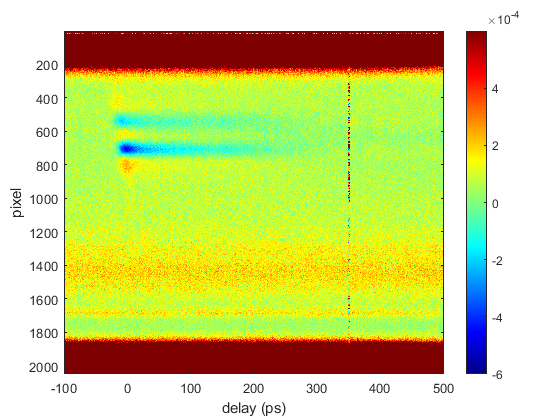


imagesc(t,linspace(1,2048,2048),flip(dtt,1))
xlabel('delay (ps)')
ylabel('pixel')
%axis([-15 750 400 875])
% axis([0 200 400 875])
colorbar
caxis([-6E-4 6E-4])
colormap(jet)



% Average two consecutive steps (n->n/2)
% dtt = dtt(:,1:6);
% dtt = reshape(dtt, [2048,2,3]);
% dtt = reshape(mean(dtt, 2), [2048,3]);

% dtt = reshape(dtt, [2048,2,78]);
% dtt = reshape(mean(dtt, 2), [2048,78]);

% Average two consecutive pixels (2048->1024)
% dtt = reshape(dtt, [2,1024,3]);
% dtt = reshape(mean(dtt, 1), [1024,3])

std(dtt(400:800,:))

ans =     0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


var(dtt(400:800,:));

#### Transient Absorption: Astrella

% Astrella_data = readmatrix ("Astrella_4s_VIS.txt");
% Astrella_data = Astrella_data.*log(10);
 
% std(Astrella_data(400:800,:))
% var(Astrella_data)

#### Plots

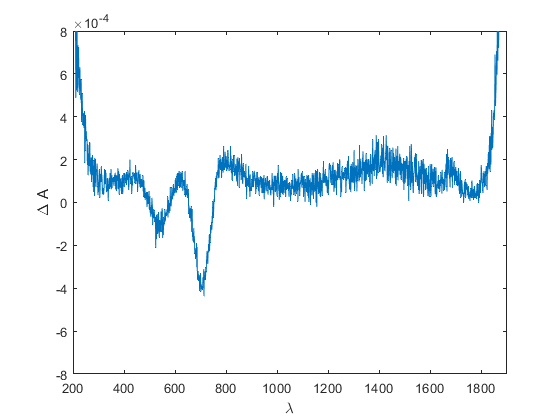

% lambda = linspace(1,2048,2048);
lambda = linspace(1,2048,2048);

% plot(lambda,Astrella_data)
% title("Astrella and Carbide TA Data")
% hold on
% plot(dtt)
% legend("Astrella", "Carbide 1", "Carbide 2", "Carbide 3")
% hold off

dtt = flip(dtt,1);   %flip wavelength order

plot(lambda,dtt(:,80))
ylabel("\Delta A")
xlabel("\lambda")
axis([200 1900 -8E-4 8E-4])


% T = 10.^(-dtt);  %Transmittance
% plot(lambda,mean(T,2))
% ylabel("T")
% xlabel("Energy")
% linspace(1,156,156)

plot(t,dtt(815,:))

Error using plot
Vectors must be the same length.

ylabel("\Delta A")
xlabel("t")
axis([0 190 -2E-4 8E-3])

% plot(t,-dtt(705,:))
plot(t,dtt(815,:))
% semilogx(t,dtt(815,:))
% axis([-1 15 -1E-4 3E-4])
%axis([200 400 -1E-4 3E-4])
% hold on 
% fitted curve
% f = fit(t',dtt(815,:)', 'power1', 'Exclude', t < 2.6E-4);
% plot(f)
% yline(0.5E-4, '--r')
ylabel("\Delta A")
xlabel("t (ps)")
text(10,2.5E-4,'\lambda = 815 nm')
% hold off